**INIT**

close all; clear all;

addpath(genpath('source'));

testImage = "lena.tif";
extension = "tif";
watermark = "res/pufferfish.mat";
alpha = 0.09;
S = 5;
watSize = 7;
resource = strcat("res/images/", testImage);
watermarked = strcat("outputs/watermarkedImages/", testImage);
attacked = strcat("outputs/attackedImages/", testImage);

**EMBED**

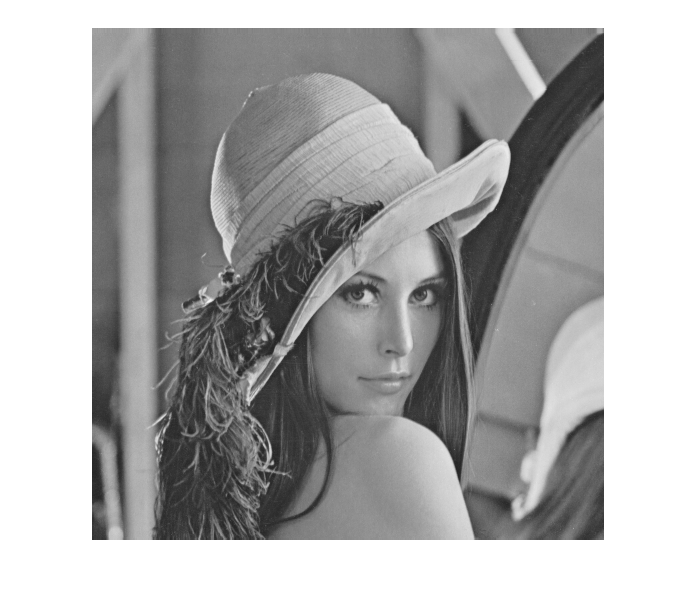

imwrite(embed(resource, watermark, alpha, S, watSize), watermarked, extension);
imshow(resource);

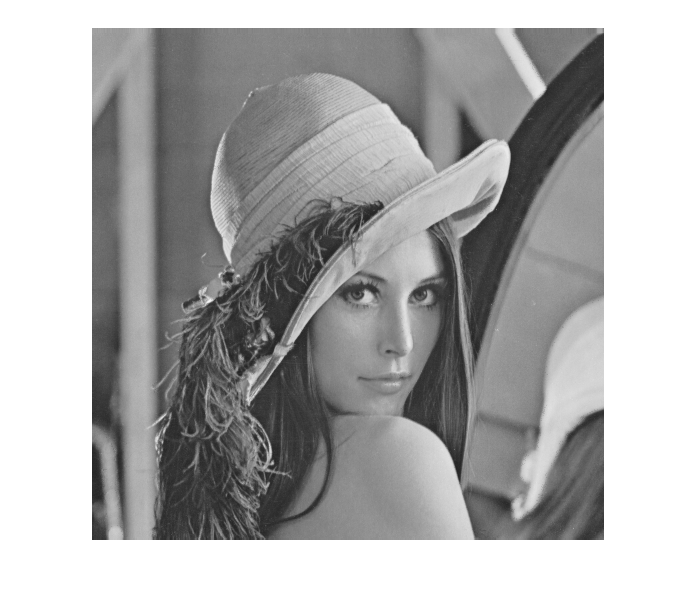

imshow(watermarked);

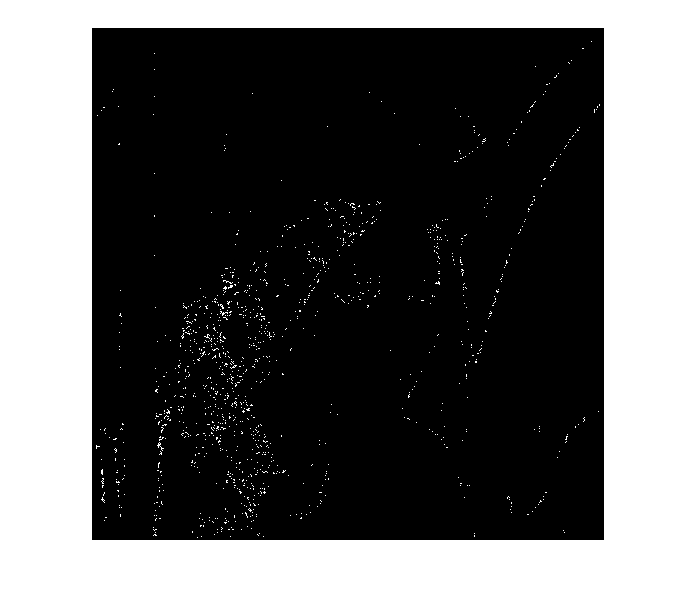


imshow((imread(watermarked) - imread(resource))*255)


PSNR(imread(resource), imread(watermarked))

PSNR = +45.94 dB


WPSNR(imread(resource), imread(watermarked))

ans = 58.1710

**ATTACK**

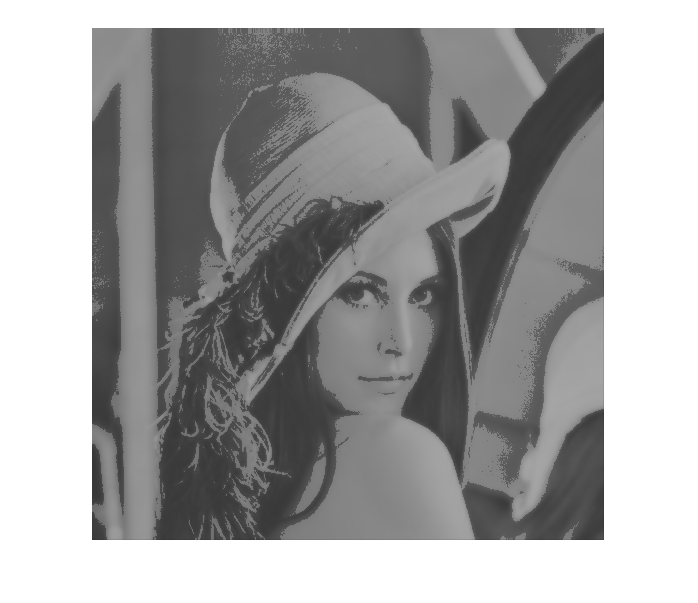

imwrite(attack(watermarked), attacked, extension);
imshow(attacked);

PSNR(imread(watermarked), imread(attacked))

PSNR = +20.47 dB


WPSNR(imread(watermarked), imread(attacked))

ans = 26.6525

**DETECT**

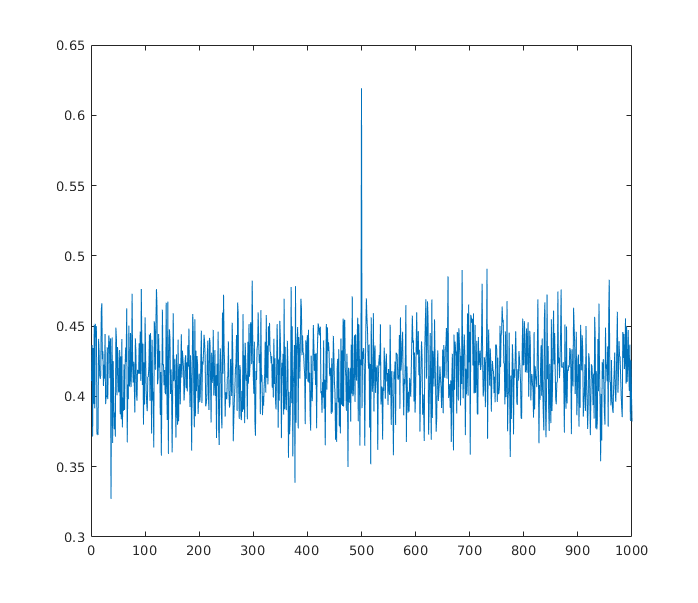

[a, b] = detect(resource, watermarked, attacked, alpha, S, watSize);

a

a = 1

b

b = 26.6525